# **Image Mosaicing**

clear;
close all;

% Read images
img1 = imread('img1.png');
img2 = imread('img2.png');
img3 = imread('img3.png');

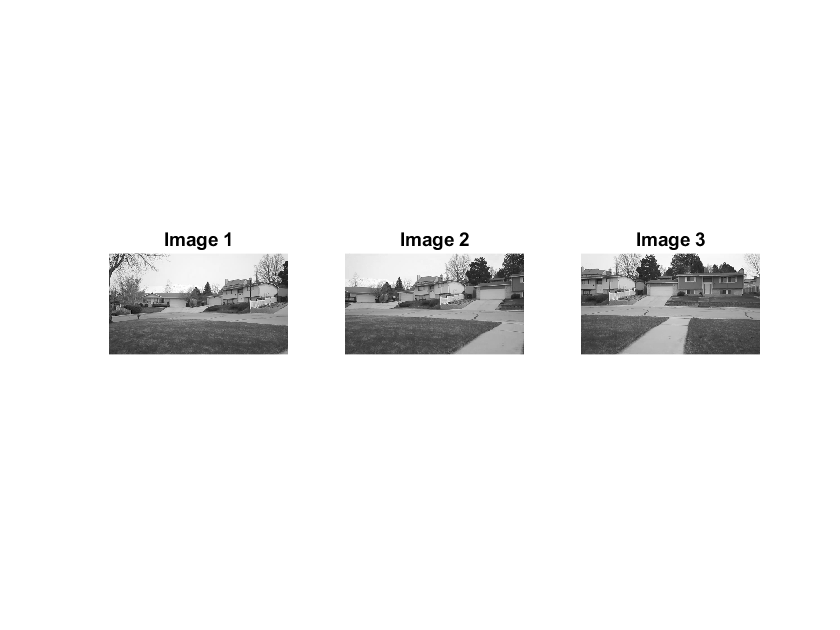

figure;
% Plot images
subplot(1,3,1);
imshow(img1);
title('Image 1');
subplot(1,3,2);
imshow(img2);
title('Image 2');
subplot(1,3,3);
imshow(img3);
title('Image 3');

## RANSAC and computing Homography

We now set the parameters for running RANSAC as described in the question. RANSAC picks the inliers in the images through SIFT and proceeds to create homography for a random 4 points. The homography is then applied on all the inliers and a consensus set is created based on the distance between the mapped location and actual location (If within epsilon, here 5, we add it to the consensus set). If the consensus set is large enough (here, 80%), then we proceed to use the homography to transform the images. 

% Set the percentile of the inlier points to be in
% consensus as 80% as given.
min_consensus = 0.8;
% epsilon- the distance between the actual 
% to homography applied points to be atleast so much
e = 5;
% Maximum no. of iterations that can be run to get a
% suitable homography
max_iter = 10^3;
% R here is |R| given, ie., the cardinality of the no.
% of point correspondances used in the computation 
% of the homography
R = 4;

% Apply SIFT and compute all corresponding points in 
% images 1 and 3 wrt 2.
[points1, points2] = sift_corresp('img1.png','img2.png');

Finding keypoints... 
1138 keypoints found. 
Finding keypoints... 
923 keypoints found. 


% Run RANSAC
H21 = ransac(points2,points1,min_consensus,R,max_iter,e);
[points3, points2] = sift_corresp('img3.png','img2.png');

Finding keypoints... 
1114 keypoints found. 
Finding keypoints... 
923 keypoints found. 


H23 = ransac(points2,points3,min_consensus,R,max_iter,e);

## Perform mosaicing

The H21 and H23 homographies are applied on images 1 and 3. Now the coordinates are with respect to image 2. We start with a canvas of width the size of the sum of the images and height the sum of the images. For the pixels across the canvas, source to target mapping is done with Bilinear interpolation. In regions where the transformed images overlap, an averaging of the pixel intensities is done.

% We add a margin one pixel wide across all images
[x,y] = size(img1);
image = zeros(x+2,y+2);
image(2:x+1,2:y+1) = img1;
img1 = image;
[x,y] = size(img2);
image = zeros(x+2,y+2);
image(2:x+1,2:y+1) = img2;
img2 = image;
[x,y] = size(img3);
image = zeros(x+2,y+2);
image(2:x+1,2:y+1) = img3;
img3 = image;
clear image;

% Get size of the images to be stitched
[x1,y1]= size(img1);
[x2,y2]= size(img2);
[x3,y3]= size(img3);

% Create a canvas of maximum dimensions
NumCanvasRows = x1+x2+x3;
NumCanvasColumns = y1+y2+y3;
canvas = zeros(NumCanvasRows,NumCanvasColumns);

% Offset as described
OffsetRow = ceil(NumCanvasRows/3);
OffsetColumn = ceil(NumCanvasColumns/3);

for ii=1:NumCanvasRows
    i = ii-OffsetRow;
    for jj=1:NumCanvasColumns
        j = jj-OffsetColumn;
        % i,j are the target locations for image 2 in the canvas
        pointsincanvas = [i j 1];
        % get source locations from homography on image 1,3
        [xs1,ys1] = apply_homography(H21,pointsincanvas);
        [xs3,ys3] = apply_homography(H23,pointsincanvas);
        % Perform bilinear interpolation
        [val1, incanvas1] = Bilinear_interpolation(img1,xs1,ys1);
        [val2, incanvas2] = Bilinear_interpolation(img2,i,j);
        [val3, incanvas3] = Bilinear_interpolation(img3,xs3,ys3);
        % A point on the canvas can be present in none to all of 
        % the images stitched. We accordingly normalize the pixel
        % intensity.
        val = val1+val2+val3;
        numincanvas = incanvas1+incanvas2+incanvas3;
        if(numincanvas>0)
            val = val/numincanvas;
        end
        canvas(ii,jj)=val;
    end
end

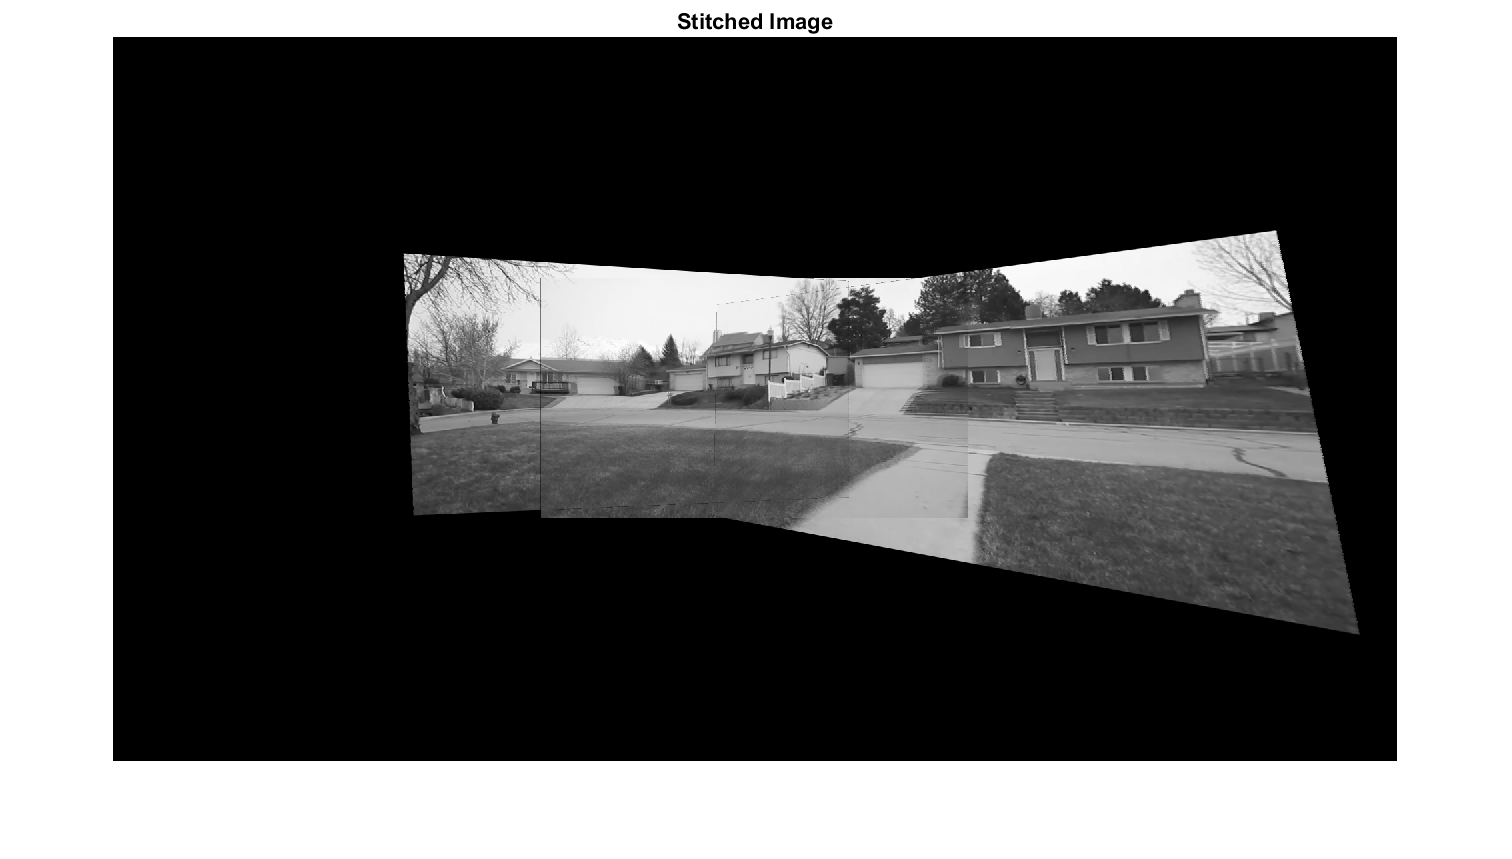

% Display canvas
canvas = uint8(canvas);
figure;
imshow(canvas);
 
title('Stitched Image');

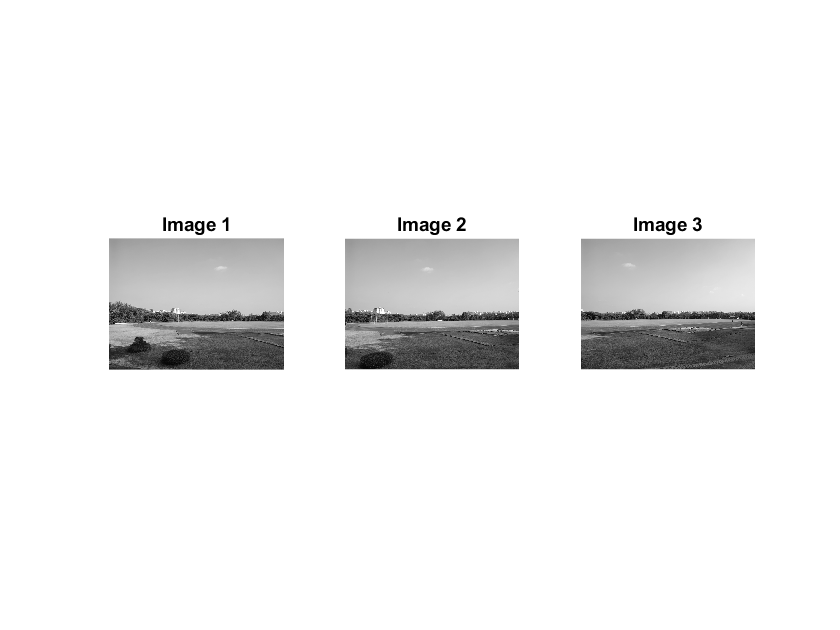

% Read images
img1 = imresize((rgb2gray(imread('captured1.jpg'))),0.2);
img2 = imresize((rgb2gray(imread('captured2.jpg'))),0.2);
img3 = imresize((rgb2gray(imread('captured3.jpg'))),0.2);
imwrite(img1,'capturedgray1.jpg');
imwrite(img2,'capturedgray2.jpg');
imwrite(img3,'capturedgray3.jpg');
figure;
% Plot images
subplot(1,3,1);
imshow(img1);
title('Image 1');
subplot(1,3,2);
imshow(img2);
title('Image 2');
subplot(1,3,3);
imshow(img3);
title('Image 3');

canvas2 = Mosaic_images('capturedgray1.jpg','capturedgray2.jpg','capturedgray3.jpg');

Finding keypoints... 
904 keypoints found. 
Finding keypoints... 
800 keypoints found. 
Finding keypoints... 
665 keypoints found. 
Finding keypoints... 
800 keypoints found. 


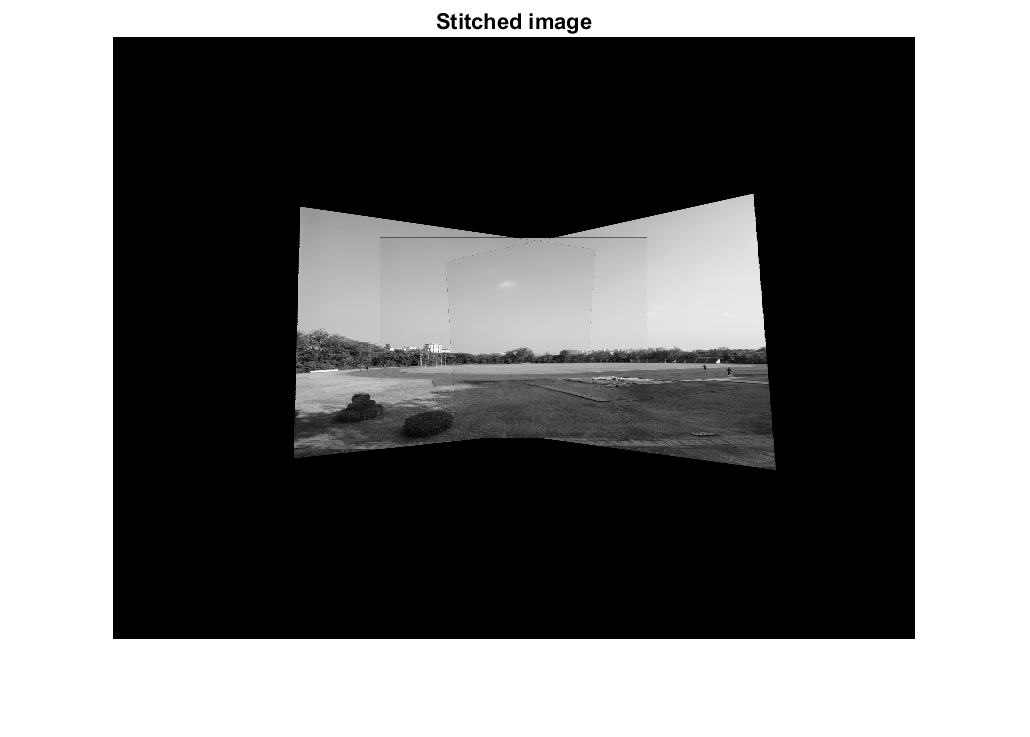

figure;
imshow(canvas2);
imwrite(canvas2,'Stitched_captured.jpg');
title('Stitched image')